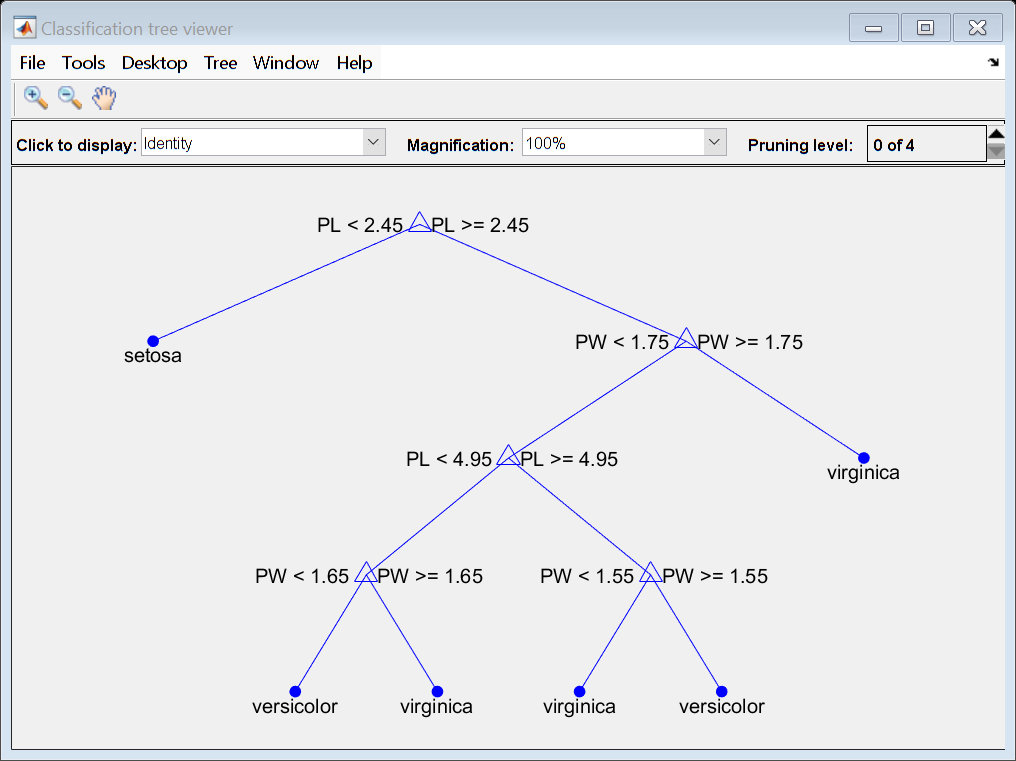

% Construct and display a full classification tree for Fisher's iris data.
% 导入数据集
load fisheriris;
varnames = {'SL','SW','PL','PW'};

% 训练分类树
t1 = fitctree(meas,species,'MinParentSize',5,'PredictorNames',varnames);
% 查看分类树结构
view(t1,'Mode','graph');  


% 计算分类模型中的损失函数
resuberror = resubLoss(t1)

resuberror = 0.0133

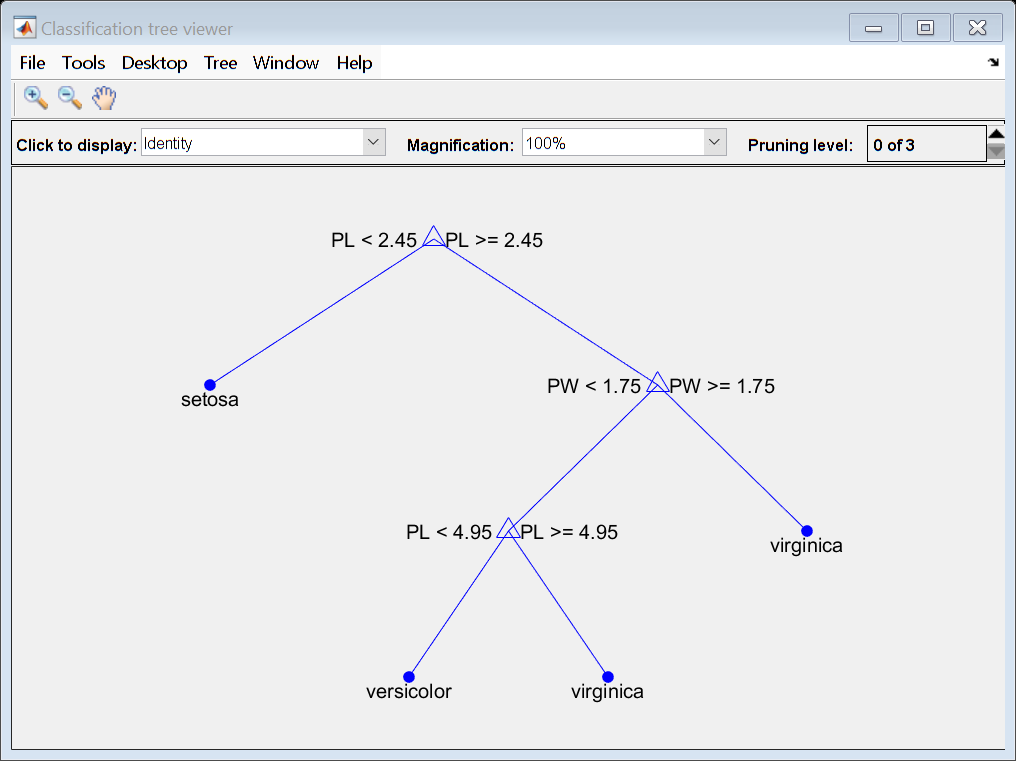


% Figure Classification tree viewer contains an axes object 
% and other objects of type uimenu, uicontrol. 
% The axes object contains 21 objects of type line, text.

% 从最优减枝序列中找到最大一个减枝后的树，
% Construct and display the next largest tree from the optimal pruning sequence.
t2 = prune(t1,'Level',1);
% 展示结构
view(t2,'Mode','graph');

% 计算分类模型中的损失函数
resuberror = resubLoss(t2)

resuberror = 0.0267